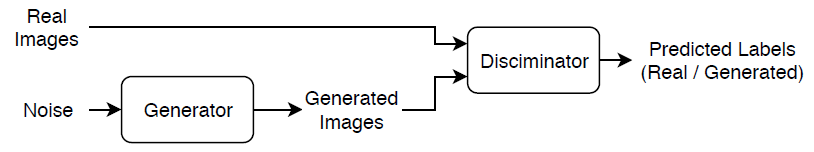

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', 'nndatasets','Dishes');
imds = imageDatastore(digitDatasetPath, 'IncludeSubfolders',true,'LabelSource','foldernames');
labelCount = countEachLabel(imds)

labelCount = 9×2 table
        Label        Count
    _____________    _____

    caesar_salad       26 
    caprese_salad      15 
    french_fries      181 
    greek_salad        24 
    hamburger         238 
    hot_dog            31 
    pizza             299 
    sashimi            40 
    sushi             124 


T = countEachLabel(imds); % Total count in each folder
% See which folders have max 29 files in them.
foldersWithEnoughFiles = T.Count == 26;
% Build a list (cell array) of all the folders.

allFolderList = cell(size(T, 1), 1);
for k = 1 : size(T, 1)
  [thisFolder, ~, ~] = fileparts(imds.Files{k});
  allFolderList{k} = thisFolder;
end

goodFolders = unique(allFolderList(foldersWithEnoughFiles));
imds_good = imageDatastore(goodFolders,'IncludeSubfolders',true,'LabelSource','foldernames');

labelCount = countEachLabel(imds_good)

labelCount = 1×2 table
       Label        Count
    ____________    _____

    caesar_salad     26  


img = readimage(imds_good,1);
size(img)

ans =    588   746     3


augmenter = imageDataAugmenter(RandXReflection=true);
augimds = augmentedImageDatastore([64 64 3],imds_good, DataAugmentation=augmenter);  

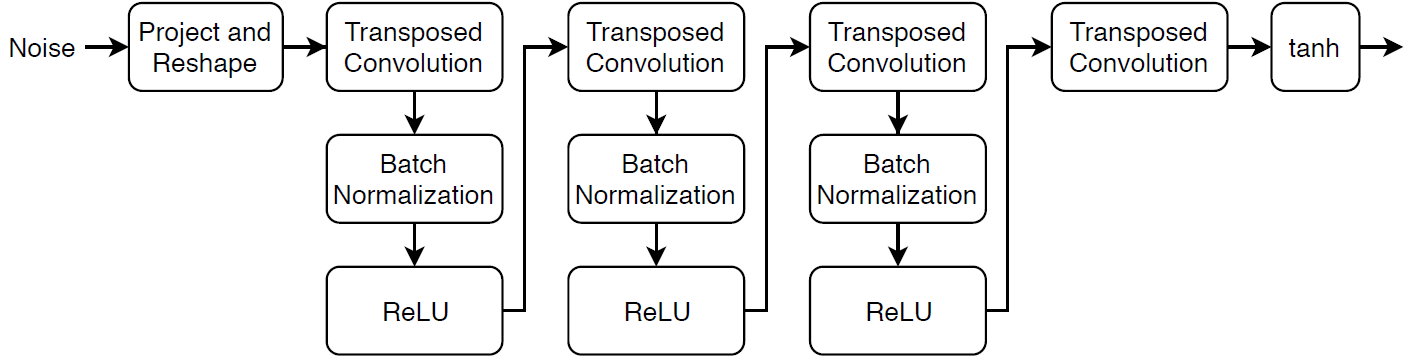

filterSize = 5;
numFilters = 64;
numLatentInputs = 100;

projectionSize = [4 4 512];

layersGenerator = [
    imageInputLayer([1 1 numLatentInputs],'Normalization','none','Name','in')
    projectAndReshapeLayer(projectionSize,numLatentInputs,'proj');
    transposedConv2dLayer(filterSize,4*numFilters,'Name','tconv1')
    batchNormalizationLayer('Name','bnorm1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(filterSize,2*numFilters,'Stride',2,'Cropping','same','Name','tconv2')
    batchNormalizationLayer('Name','bnorm2')
    reluLayer('Name','relu2')
   
    transposedConv2dLayer(filterSize,numFilters,'Stride',2,'Cropping','same','Name','tconv3')
    batchNormalizationLayer('Name','bnorm3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(filterSize,3,'Stride',2,'Cropping','same','Name','tconv4')
    tanhLayer('Name','tanh')];

lgraphGenerator = layerGraph(layersGenerator);
dlnetGenerator = dlnetwork(lgraphGenerator);
%analyzeNetwork(lgraphGenerator);

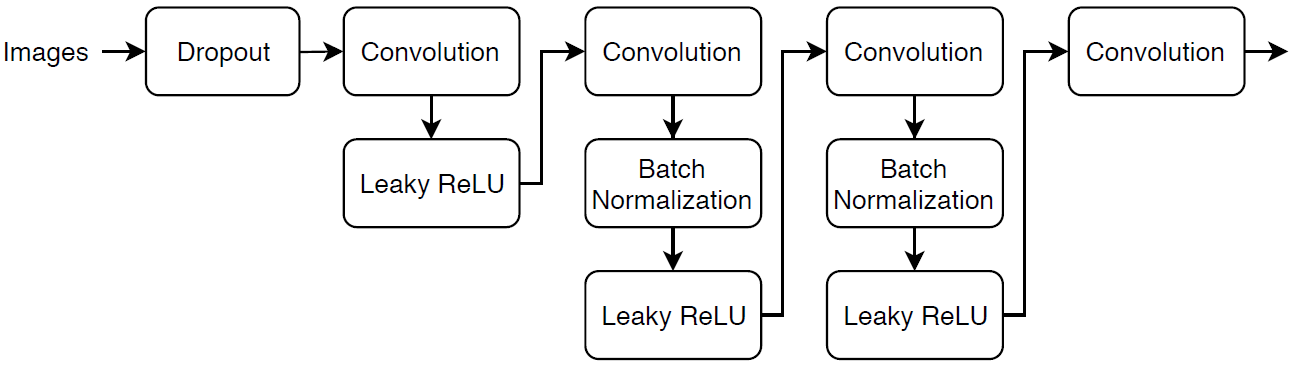

dropoutProb = 0.5;
numFilters = 64;
scale = 0.2;

inputSize = [64 64 3];
filterSize = 5;

layersDiscriminator = [
    imageInputLayer(inputSize,'Normalization','none','Name','in')
    dropoutLayer(0.5,'Name','dropout')
    convolution2dLayer(filterSize,numFilters,'Stride',2,'Padding','same','Name','conv1')
    leakyReluLayer(scale,'Name','lrelu1')
    convolution2dLayer(filterSize,2*numFilters,'Stride',2,'Padding','same','Name','conv2')
    batchNormalizationLayer('Name','bn2')
    leakyReluLayer(scale,'Name','lrelu2')
    convolution2dLayer(filterSize,4*numFilters,'Stride',2,'Padding','same','Name','conv3')
    batchNormalizationLayer('Name','bn3')
    leakyReluLayer(scale,'Name','lrelu3')
    
    convolution2dLayer(filterSize,8*numFilters,'Stride',2,'Padding','same','Name','conv4')
    batchNormalizationLayer('Name','bn4')
    leakyReluLayer(scale,'Name','lrelu4')
    convolution2dLayer(4,1,'Name','conv5')];

lgraphDiscriminator = layerGraph(layersDiscriminator);
dlnetDiscriminator = dlnetwork(lgraphDiscriminator);
%analyzeNetwork(lgraphDiscriminator);

numEpochs = 500;
miniBatchSize = 4;
augimds.MiniBatchSize = miniBatchSize;

learnRate = 0.0002;
gradientDecayFactor = 0.5;
squaredGradientDecayFactor = 0.999;
executionEnvironment = "auto";

flipFactor = 0.3;
validationFrequency = 50;

trailingAvgGenerator = [];
trailingAvgSqGenerator = [];
trailingAvgDiscriminator = [];
trailingAvgSqDiscriminator = [];

numValidationImages = 25;
ZValidation = randn(1,1,numLatentInputs,numValidationImages,'single');

dlZValidation = dlarray(ZValidation,'SSCB');

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZValidation = gpuArray(dlZValidation);
end

f = figure;
f.Position(3) = 2*f.Position(3);

imageAxes = subplot(1,2,1);
scoreAxes = subplot(1,2,2);

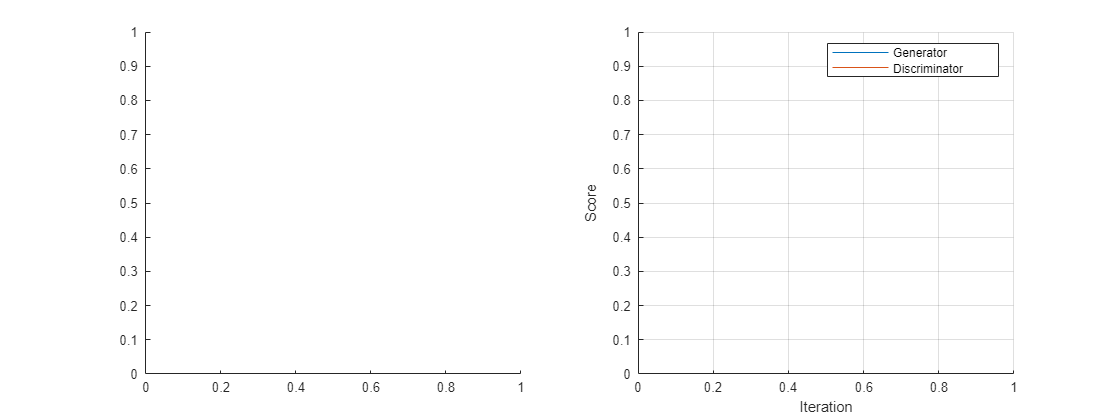

lineScoreGenerator = animatedline(scoreAxes,'Color',[0 0.447 0.741]);
lineScoreDiscriminator = animatedline(scoreAxes, 'Color', [0.85 0.325 0.098]);
legend('Generator','Discriminator');
ylim([0 1])
xlabel("Iteration")
ylabel("Score")
grid on

iteration = 0;
start = tic;


if exist('gen_ceasar.mat',"file")
    load('gen_ceasar.mat') 
end

if exist('disc_ceasar.mat',"file")
    load('disc_ceasar.mat')
end

if ~exist('disc_ceasar.mat',"file")
    if ~exist('gen_ceasar.mat',"file")
        
        
        for epoch = 1:numEpochs
            %save('gen.mat','dlnetGenerator',"-mat");
            %save('disc.mat','dlnetDiscriminator',"-mat");

            reset(augimds);
            augimds = shuffle(augimds);
            
            
            while hasdata(augimds)
                iteration = iteration + 1;
                
               
                data = read(augimds);
                
               
                if size(data,1) < miniBatchSize
                    continue
                end
                
                
                
                X = cat(4,data{:,1}{:});
                X = single(X);
                
                Z = randn(1,1,numLatentInputs,size(X,4),'single');
                
                
                X = rescale(X,-1,1,'InputMin',0,'InputMax',255);
                
                
                dlX = dlarray(X, 'SSCB');
                dlZ = dlarray(Z, 'SSCB');
                
                
                if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
                    dlX = gpuArray(dlX);
                    dlZ = gpuArray(dlZ);
                end
                
                
                [gradientsGenerator, gradientsDiscriminator, stateGenerator, scoreGenerator, scoreDiscriminator] = ...
                    dlfeval(@modelGradients, dlnetGenerator, dlnetDiscriminator, dlX, dlZ, flipFactor);
                dlnetGenerator.State = stateGenerator;
                
                
                [dlnetDiscriminator,trailingAvgDiscriminator,trailingAvgSqDiscriminator] = ...
                    adamupdate(dlnetDiscriminator, gradientsDiscriminator, ...
                    trailingAvgDiscriminator, trailingAvgSqDiscriminator, iteration, ...
                    learnRate, gradientDecayFactor, squaredGradientDecayFactor);
                
         
                [dlnetGenerator,trailingAvgGenerator,trailingAvgSqGenerator] = ...
                    adamupdate(dlnetGenerator, gradientsGenerator, ...
                    trailingAvgGenerator, trailingAvgSqGenerator, iteration, ...
                    learnRate, gradientDecayFactor, squaredGradientDecayFactor);
     
                if mod(iteration,validationFrequency) == 0 || iteration == 1
                   
                    dlXGeneratedValidation = predict(dlnetGenerator,dlZValidation);
                    
          
                    I = imtile(extractdata(dlXGeneratedValidation));
                    I = rescale(I);
                    subplot(1,2,1);
                    image(imageAxes,I)
                    xticklabels([]);
                    yticklabels([]);
                    title("Generated Images");
                end
                
                
                subplot(1,2,2)
                addpoints(lineScoreGenerator,iteration,...
                    double(gather(extractdata(scoreGenerator))));
                
                addpoints(lineScoreDiscriminator,iteration,...
                    double(gather(extractdata(scoreDiscriminator))));
                
                
                D = duration(0,0,toc(start),'Format','hh:mm:ss');% toc - значение таймера, пишем прошедшее время в заголовке
                title(...
                    "Epoch: " + epoch + ", " + ...
                    "Iteration: " + iteration + ", " + ...
                    "Elapsed: " + string(D))
                       drawnow
            end
        end
    end 
end        

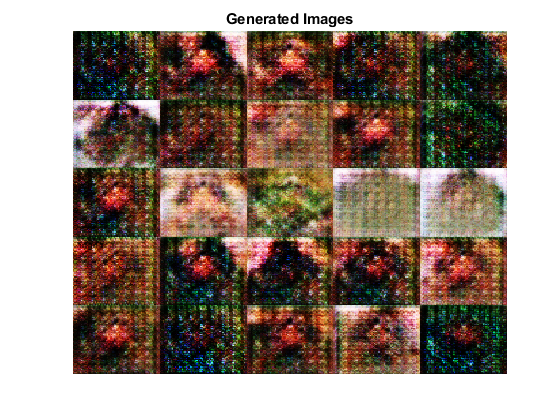

save('gen_ceasar.mat','dlnetGenerator',"-mat");
save('disc_ceasar.mat','dlnetDiscriminator',"-mat");

ZNew = randn(1,1,numLatentInputs,numValidationImages,'single');
dlZNew = dlarray(ZNew,'SSCB');
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZNew = gpuArray(dlZNew);
end
dlXGeneratedNew = predict(dlnetGenerator,dlZNew);
I = imtile(extractdata(dlXGeneratedNew));
I = rescale(I);
figure
image(I)
axis off
title("Generated Images") 

ZNew2 = randn(1,1,numLatentInputs,100,'single');
dlZNew2 = dlarray(ZNew2,'SSCB');
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZNew = gpuArray(dlZNew);
end
test_image = predict(dlnetGenerator,dlZNew2);
size(test_image)

ans =     64    64     3   100


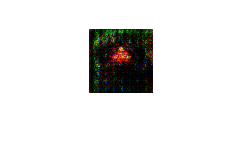

for i = 1:100
    test_sub_image = squeeze(test_image(:,:,:,i));
    test_sub_image = extractdata(test_sub_image);
    test_sub_image = rescale(test_sub_image);
    imshow(test_sub_image);
    %folder = 'C:\Users\flemblade\MTLB';
    %size(test_image)
    %Image = getframe(gcf);
    imwrite(double(test_sub_image), 'caesar'+string(i)+'.jpg');
end

function [gradientsGenerator, gradientsDiscriminator, stateGenerator, scoreGenerator, scoreDiscriminator] = ...
    modelGradients(dlnetGenerator, dlnetDiscriminator, dlX, dlZ, flipFactor)

dlYPred = forward(dlnetDiscriminator, dlX);


[dlXGenerated,stateGenerator] = forward(dlnetGenerator,dlZ);

dlYPredGenerated = forward(dlnetDiscriminator, dlXGenerated);


probGenerated = sigmoid(dlYPredGenerated);
probReal = sigmoid(dlYPred);


scoreDiscriminator = ((mean(probReal)+mean(1-probGenerated))/2);


scoreGenerator = mean(probGenerated);


numObservations = size(probReal,4);
idx = randperm(numObservations,floor(flipFactor * numObservations));% случайные индексы


probReal(:,:,:,idx) = 1-probReal(:,:,:,idx);


[lossGenerator, lossDiscriminator] = ganLoss(probReal,probGenerated);


gradientsGenerator = dlgradient(lossGenerator, dlnetGenerator.Learnables,'RetainData',true);
gradientsDiscriminator = dlgradient(lossDiscriminator, dlnetDiscriminator.Learnables);

end

function [lossGenerator, lossDiscriminator] = ganLoss(probReal,probGenerated)


lossDiscriminator =  -mean(log(probReal)) -mean(log(1-probGenerated));


lossGenerator = -mean(log(probGenerated));

end